# Lab - MATLAB Review 2

**Topics: **Going from flow chart to code, functions, conditionals

## Average temperature problem

calls ***averageTempCalculator***

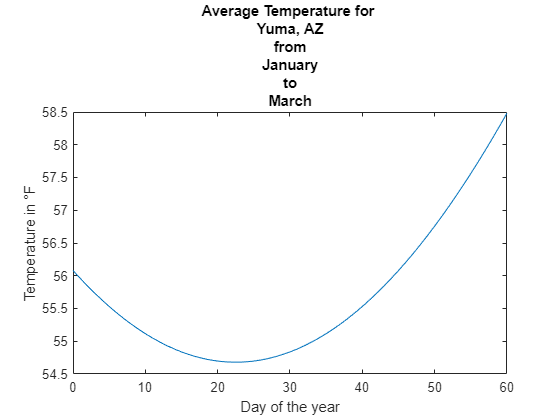

% Test #1 invalid cities

% H_Temp = averageTempCalculator('Huntsville, AL', 0, 60)

% Test #2 plotting
averageTempCalculator("Yuma, AZ", 0, 60)


% Test #3 average temperature
Yuma_Temp = averageTempCalculator("Yuma, AZ", 0, 60)

Yuma_Temp = 55.6864


% Test #4 default values
Yuma_Temp = averageTempCalculator("Yuma, AZ")

Yuma_Temp = 73.5322

## Helper functions

### averageTempCalculator - Calculate average temperature given city and range of days

**1) Set up function declaration**

function avgTemp = averageTempCalculator(city, startDay, stopDay)
% AVERAGETEMPCALCULATOR - calculates the overall average temperatures for a given city and range of days
% Usage:
%      avgTemp = averageTempCalculator(city, startDay, stopDay) - return overall average temperature for the range 
%      averageTempCalculator(city, startDay, stopDay) - plot daily average temps in deg. Fahrenheit

% Arguments:
%   city - the name of a city as a text string
%   startDay - the first day of the range as an integer (default 0)
%   stopDay - the last day of the range as an integer  (default 365)
% Returns:
%   avgTemp - the overall average temperature for the range  in degrees F
% Calls:  celsiusToFahrenheit and getMonth



**2) Set up data matrix**

|    CITY         | T_mean (deg C)    | T_peak (deg C)  |

| Miami, FL     |        22.1                 | 28.3                   |

| Yuma, AZ     |        23.1                 | 33.6                   |

| Bismark, ND |         5.2                  | 22.1                  |

| Seattle, WA   |        10.6                 | 17.6                  |

| Boston, MA   |        10.7                 | 22.9                  |

TempData = [22.1, 28.3;
            23.1, 33.6;
            5.2, 22.1;
            10.6, 17.6;
            10.7, 22.9];
%first column- mean temp
%second column- peak temp
%rows correspond to cities

**3) See if city values are defined**

Cities = ["Miami, FL", "Yuma, AZ", "Bismark, ND", "Seattle, WA", "Boston, MA"];     %List of cities

for n =  1:length(Cities)           %cycle through cities
    if strcmp(city, Cities(n))      %compare input to list
        index = n;                  %index imput city
        break
    elseif ismember(city, Cities)
        n=n+1;
    else
        error(['Function does not have temperature data for ' city ' defined.'])
    end
end



**4) Calculate values**

$\omega =\frac{2\pi }{365}$, $t_{\textrm{peak}} =205$, $T=T_{\textrm{mean}} +\left(T_{\textrm{peak}} -T_{\textrm{mean}} \right)\cos \left(\omega \left(t-t_{\textrm{peak}} \right)\right)$

omega = 2*pi/365;       %Frequency
t_peak = 205;           %time of peak temperature
if nargin == 1
    startDay = 0;
    stopDay = 365;
end
t = startDay:stopDay;   %Time Vector
Temperature = TempData(index,1) + (TempData(index,2) - TempData(index,1)) *cos(omega*(t-t_peak));

**5) Convert from degrees Celsius to degrees Fahrenheit**

Temperature = celsiusToFahrenheit(Temperature);

**6) Either plot or calculate average**

if nargout == 1
    avgTemp = mean(Temperature);
else
    plot(t,Temperature)
    xlabel("Day of the year")
    ylabel("Temperature in °F")
    title(['Average Temperature for ' city ' from ' getMonth(startDay) ' to ' getMonth(stopDay)])
end
end

### celsiusToFahrenheit - Convert Celsius to Fahrenheit

function fahrenheit = celsiusToFahrenheit(Celsius)
    fahrenheit = 9/5*Celsius + 32;
end

### getMonth - Get month associated with integer day of year

function month = getMonth(day)
% GETMONTH - gets the month given an integer representing a day in the year
% Argument:
%   day - day of the year as an integer (from 0 to 365)
% Returns:
%   month - the month corresponding to the given day as a string)
    if day >= 0 && day < 31
        month = 'January';
    elseif day >= 31 && day  < 59
        month = 'February';
    elseif day >= 59 && day < 90
        month = 'March';
    elseif day >= 90 && day < 120
        month = 'April';
    elseif day >= 120 && day < 151
        month = 'May';
    elseif day >= 151 && day < 181
        month = 'June';
    elseif day >= 181 && day < 212
        month = 'July';
    elseif day >= 212 && day < 243
        month = 'August';
    elseif day >= 243 && day < 273
        month = 'September';
    elseif day >= 273 && day < 304
        month = 'October';
    elseif day >= 304 && day < 334
        month = 'November';
    elseif day >= 334 & day <= 365
        month = 'December';
    else
        error(['Day provided, ' day, ' is not in the range 0 to 365'])
    end
end